Stanford manipulator analysis

ME586

Aaron Cornelius

2020-9-8

Start with the origin at the interesection of axis 1 and axis 2, as shown below. 

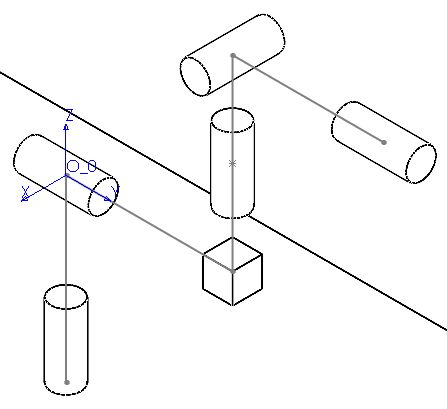

This is the most convenient place to locate the origin since it means there is no translation when moving between the two, only rotation. The transformation $A_1^0$ is therefore purely two rotations, a rotation around $Z_0$ by $\vartheta_1$ and a rotation around the $X_0$ by $-\frac{\;\pi \;}{2}$:


$$A_1^0 \left(\vartheta_1 \right)=R_Z \left(\vartheta_1 \right)R_X \left(-\frac{\pi \;}{2}\right)=\left\lbrack \begin{array}{cccc}
\mathrm{cos}\left(\vartheta_1 \right) & -\mathrm{sin}\left(\vartheta_1 \right) & 0 & 0\\
\mathrm{sin}\left(\vartheta_1 \right) & \mathrm{cos}\left(\vartheta_1 \right) & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & \mathrm{cos}\left(-\frac{\pi \;}{2}\right) & -\mathrm{sin}\left(-\frac{\pi \;}{2}\right) & 0\\
0 & \mathrm{sin}\left(-\frac{\pi \;}{2}\right) & \mathrm{cos}\left(-\frac{\pi \;}{2}\right) & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$



$$\Rightarrow A_1^0 \left(\vartheta_1 \right)=\left\lbrack \begin{array}{cccc}
\mathrm{cos}\left(\vartheta_1 \right) & -\mathrm{sin}\left(\vartheta_1 \right) & 0 & 0\\
\mathrm{sin}\left(\vartheta_1 \right) & \mathrm{cos}\left(\vartheta_1 \right) & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 0 & 1 & 0\\
0 & -1 & 0 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
c_1  & 0 & -s_1  & 0\\
s_1  & 0 & c_1  & 0\\
0 & -1 & 0 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


syms vartheta_1
A01 = RotateZ(vartheta_1)*RotateX(sym(-pi/2));

This transformation will place the new origin $O_1$ as shown below:

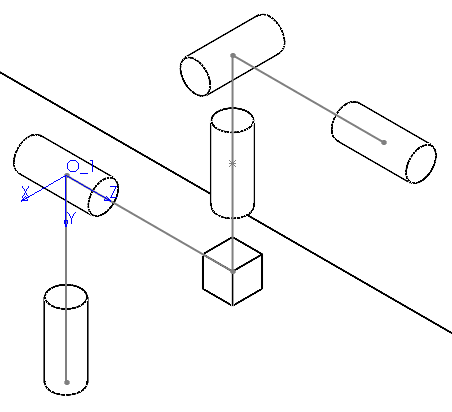

The next transformation will rotate around $Z_1$by $\vartheta_2$, translate it along $Z_2$ $d_2$, and then rotate around the current X axis by $\frac{\pi }{2}$ to get $O_2$ at the intersection of the A_2 rotary join and the A_4 rotary joint. This is chosen because A_4 is a prismatic axis: there is no proscribed axis for the new Z axis to point, just a direction. Therefore, the transformation $A_2^1$ is:


$$A_2^1 =R_Z \left(\vartheta_2 \right)T_Z \left(d_2 \right)R_X \left(\frac{\pi }{2}\right)=\left\lbrack \begin{array}{cccc}
c_2  & -s_2  & 0 & 0\\
s_2  & c_2  & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & d_2 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & \mathrm{cos}\left(\frac{\pi \;}{2}\right) & -\mathrm{sin}\left(\frac{\pi \;}{2}\right) & 0\\
0 & \mathrm{sin}\left(\frac{\pi \;}{2}\right) & \mathrm{cos}\left(\frac{\pi \;}{2}\right) & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$



$$\Rightarrow A_2^1 =\left\lbrack \begin{array}{cccc}
c_2  & -s_2  & 0 & 0\\
s_2  & c_2  & 0 & 0\\
0 & 0 & 1 & d_2 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & d_2 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack \cdot \;\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 0 & -1 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
c_2  & 0 & s_2  & 0\\
s_2  & 0 & -c_2  & 0\\
0 & 1 & 0 & d_2 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


syms vartheta_2 d_2
A12 = RotateZ(vartheta_2)*TranslateZ(d_2)*RotateX(sym(pi/2));

This places the new origin $O_2$ here:

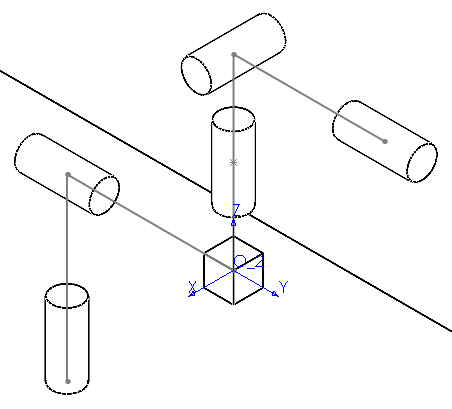

The next axis is a simple translation along $Z$. For convenience, this translation will place the origin at the intersection of axes 4 and 5.


$$A_3^2 =T_Z \left(d_3 \right)=\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & d_3 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


syms d_3
A23 = TranslateZ(d_3);

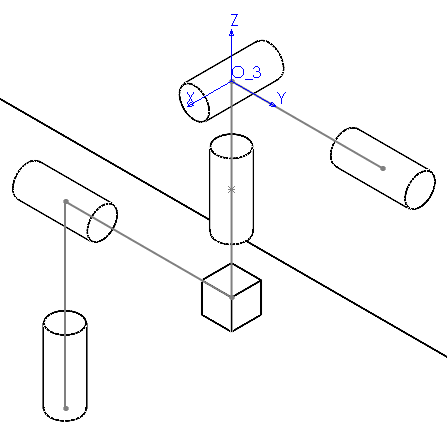

Next, this is rotated around the Z axis by $\vartheta_4$ and rotated by $-\frac{\pi }{2}$ around X. Note that, for this transformation to be correct, the drawing shows the axes when $\vartheta_4 =-\frac{\pi }{2}$. The drawing was done this way to be consistent with the book. If this is not kept in mind, then a rotation solely around X would appear to be impossible.


$$A_4^3 =R_Z \left(\vartheta_4 \right)R_x \left(-\frac{\pi }{2}\right)=\left\lbrack \begin{array}{cccc}
\mathrm{cos}\left(\vartheta_4 \right) & -\mathrm{sin}\left(\vartheta_4 \right) & 0 & 0\\
\mathrm{sin}\left(\vartheta_4 \right) & \mathrm{cos}\left(\vartheta_4 \right) & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & \mathrm{cos}\left(-\frac{\pi \;}{2}\right) & -\mathrm{sin}\left(-\frac{\pi \;}{2}\right) & 0\\
0 & \mathrm{sin}\left(-\frac{\pi \;}{2}\right) & \mathrm{cos}\left(-\frac{\pi \;}{2}\right) & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$



$$A_4^3 =\left\lbrack \begin{array}{cccc}
\mathrm{cos}\left(\vartheta_4 \right) & -\mathrm{sin}\left(\vartheta_4 \right) & 0 & 0\\
\mathrm{sin}\left(\vartheta_4 \right) & \mathrm{cos}\left(\vartheta_4 \right) & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 0 & 1 & 0\\
0 & -1 & 0 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
c_4  & 0 & -s_4  & 0\\
s_4  & 0 & c_4  & 0\\
0 & -1 & 0 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


syms vartheta_4
A34 = RotateZ(vartheta_4)*RotateX(sym(-pi/2));

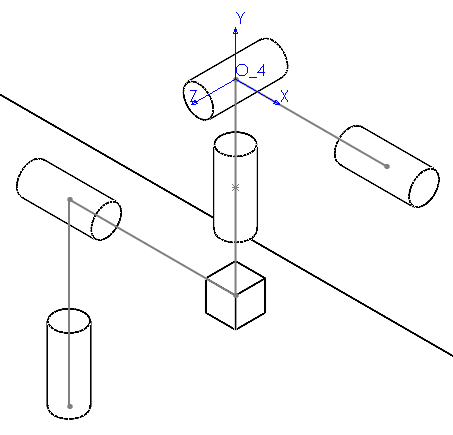

The axis rotation $\vartheta_5$ around Z is applied, then a rotation around X of $\frac{\pi }{2}$ aligns the Z axis parallel with the last joint. (Note that this is difficult to visualize in the picture since, to keep the picture similar to the book, axis 5 appears to be shown at $\vartheta_5 =-\frac{\pi }{2}$, not 0.)


$$A_5^4 =R_Z \left(\vartheta_5 \right)R_X \left(\frac{\pi }{2}\right)=\left\lbrack \begin{array}{cccc}
\mathrm{cos}\left(\vartheta_5 \right) & -\mathrm{sin}\left(\vartheta_5 \right) & 0 & 0\\
\mathrm{sin}\left(\vartheta_5 \right) & \mathrm{cos}\left(\vartheta_5 \right) & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & \mathrm{cos}\left(\frac{\pi \;}{2}\right) & -\mathrm{sin}\left(\frac{\pi \;}{2}\right) & 0\\
0 & \mathrm{sin}\left(\frac{\pi \;}{2}\right) & \mathrm{cos}\left(\frac{\pi \;}{2}\right) & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$



$$A_5^4 =\left\lbrack \begin{array}{cccc}
\mathrm{cos}\left(\vartheta_5 \right) & -\mathrm{sin}\left(\vartheta_5 \right) & 0 & 0\\
\mathrm{sin}\left(\vartheta_5 \right) & \mathrm{cos}\left(\vartheta_5 \right) & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 0 & -1 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
c_5  & 0 & s_5  & 0\\
s_5  & 0 & {-c}_5  & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


syms vartheta_5
A45 = RotateZ(vartheta_5)*RotateX(sym(pi/2));

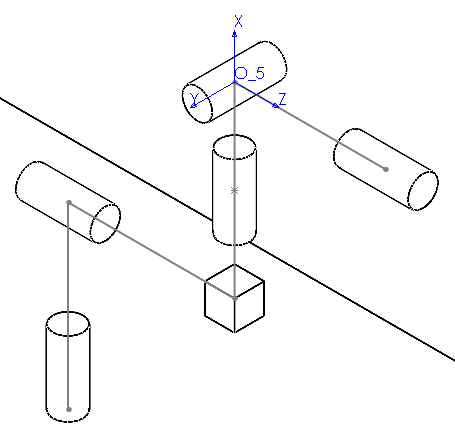

Finally, the rotation of the sixth axis around Z is applied, and the origin is translated out along the Z axis vector to the gripper coordinates (shown here at the end of the rotary axis, but the position is arbitrary.)


$$A_6^5 =R_Z \left(\vartheta_6 \right)T_Z \left(d_6 \right)=\left\lbrack \begin{array}{cccc}
c_6  & -s_6  & 0 & 0\\
s_6  & c_6  & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & d_6 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
c_6  & -s_6  & 0 & 0\\
s_6  & c_6  & 0 & 0\\
0 & 0 & 1 & d_2 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


syms vartheta_6 d_6
A56 = RotateZ(vartheta_6)*TranslateZ(d_6);

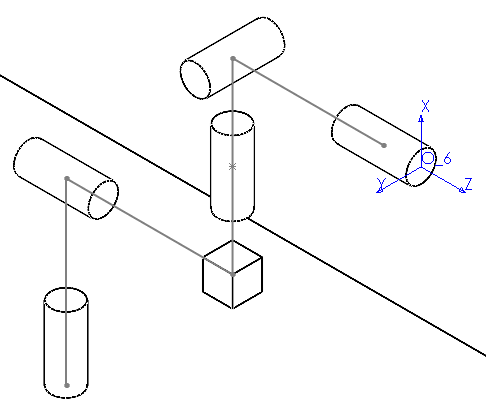

Now that all the individual axis transformations are determined, the whole transformation can be found by multiplying $A_1^0 A_2^1 A_3^2 A_4^3 A_5^4 A_6^5 =A_6^0$. This matrix will be solved symbolically, since the multiplication is trivial but time-consuming. This can then be broken up into the four manipulator frame vectors. First, the position:

syms s1 s2 s3 s4 s5 s6 c1 c2 c3 c4 c5 c6
A06 = subs(A01*A12*A23*A34*A45*A56, ...
    [sin(vartheta_1) sin(vartheta_2) sin(vartheta_4) sin(vartheta_5) sin(vartheta_6) ...
    cos(vartheta_1) cos(vartheta_2) cos(vartheta_4) cos(vartheta_5) cos(vartheta_6)], ...
    [s1 s2 s4 s5 s6 c1 c2 c4 c5 c6]);

This can then be broken up into the four manipulator frame vectors. First, the position vector:

A06(1:3, 4)

$$ans = \left(\begin{array}{c} c_{1}\,d_{3}\,s_{2}-d_{6}\,\left(s_{5}\,\left(s_{1}\,s_{4}-c_{1}\,c_{2}\,c_{4}\right)-c_{1}\,c_{5}\,s_{2}\right)-d_{2}\,s_{1}\\ c_{1}\,d_{2}+d_{6}\,\left(s_{5}\,\left(c_{1}\,s_{4}+c_{2}\,c_{4}\,s_{1}\right)+c_{5}\,s_{1}\,s_{2}\right)+d_{3}\,s_{1}\,s_{2}\\ c_{2}\,d_{3}+d_{6}\,\left(c_{2}\,c_{5}-c_{4}\,s_{2}\,s_{5}\right) \end{array}\right)$$

Second, the normal vector:

A06(1:3, 1)

$$ans = \left(\begin{array}{c} -c_{6}\,\left(c_{5}\,\left(s_{1}\,s_{4}-c_{1}\,c_{2}\,c_{4}\right)+c_{1}\,s_{2}\,s_{5}\right)-s_{6}\,\left(c_{4}\,s_{1}+c_{1}\,c_{2}\,s_{4}\right)\\ c_{6}\,\left(c_{5}\,\left(c_{1}\,s_{4}+c_{2}\,c_{4}\,s_{1}\right)-s_{1}\,s_{2}\,s_{5}\right)+s_{6}\,\left(c_{1}\,c_{4}-c_{2}\,s_{1}\,s_{4}\right)\\ s_{2}\,s_{4}\,s_{6}-c_{6}\,\left(c_{2}\,s_{5}+c_{4}\,c_{5}\,s_{2}\right) \end{array}\right)$$

Third, the sliding vector:

A06(1:3, 2)

$$ans = \left(\begin{array}{c} s_{6}\,\left(c_{5}\,\left(s_{1}\,s_{4}-c_{1}\,c_{2}\,c_{4}\right)+c_{1}\,s_{2}\,s_{5}\right)-c_{6}\,\left(c_{4}\,s_{1}+c_{1}\,c_{2}\,s_{4}\right)\\ c_{6}\,\left(c_{1}\,c_{4}-c_{2}\,s_{1}\,s_{4}\right)-s_{6}\,\left(c_{5}\,\left(c_{1}\,s_{4}+c_{2}\,c_{4}\,s_{1}\right)-s_{1}\,s_{2}\,s_{5}\right)\\ s_{6}\,\left(c_{2}\,s_{5}+c_{4}\,c_{5}\,s_{2}\right)+c_{6}\,s_{2}\,s_{4} \end{array}\right)$$

And fourth, the approach vector:

A06(1:3, 3)

$$ans = \left(\begin{array}{c} c_{1}\,c_{5}\,s_{2}-s_{5}\,\left(s_{1}\,s_{4}-c_{1}\,c_{2}\,c_{4}\right)\\ s_{5}\,\left(c_{1}\,s_{4}+c_{2}\,c_{4}\,s_{1}\right)+c_{5}\,s_{1}\,s_{2}\\ c_{2}\,c_{5}-c_{4}\,s_{2}\,s_{5} \end{array}\right)$$

function rVal = RotateX(theta)
    rVal = sym([ 1 0 0 0;
        0 cos(theta) -sin(theta) 0; ...
        0 sin(theta) cos(theta) 0; ...
        0 0 0 1 ...
        ]);
end
function mat = RotateY(theta)
    mat =  sym([...
        cos(theta) 0 sin(theta) 0; ...
        0 1 0 0; ...
        -sin(theta) 0 cos(theta) 0; ...
        0 0 0 1 ...
    ]);
end
function mat = RotateZ(theta)
    mat =  sym([...
        cos(theta) -sin(theta) 0 0; ...
        sin(theta) cos(theta) 0 0; ...
        0 0 1 0; ...
        0 0 0 1 ...
        ]);
end
function mat = TranslateX(d)
    mat = sym([...
        1   0   0   d; ...
        0   1   0   0; ...
        0   0   1   0; ...
        0   0   0   1  ...
        ]);
end
function mat = TranslateY(d)
    mat = sym([...
        1   0   0   0; ...
        0   1   0   d; ...
        0   0   1   0; ...
        0   0   0   1  ...
        ]);
end
function mat = TranslateZ(d)
    mat = sym([...
        1   0   0   0; ...
        0   1   0   0; ...
        0   0   1   d; ...
        0   0   0   1  ...
        ]);
end